clear all
close all
clc

rng(1);


testData = load('wiener/WH_TestDataset');
trainData = load('wiener/WH_EstimationExample');

% load('wiener/WH_SineInput_meas')
% 

% load('wiener/WH_CombinedZeroMultisineSinesweep')




% uEst=smoothdata(uEst,'gaussian',2);
% yEst=smoothdata(yEst,'gaussian',2);


% plot(trainData.u(1:20000,1))
% plot(trainData.y(1:20000,1))
% 
% plot(testData.r(:,1))
% plot(testData.y)

Preprocessing Data

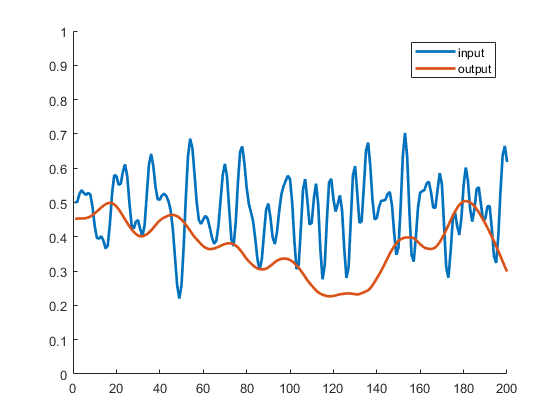

tic

% input = [trainData.u(1:20000,1)/8+0.5  ; trainData.u(1:20000,2)/8+0.5];
% output = [trainData.y(1:20000,1)/0.8+0.5;trainData.y(1:20000,2)/0.8+0.5];

input = trainData.dataMeas.u(:)/8+0.5;
output = trainData.dataMeas.y(:)/0.8+0.5;

tinput = testData.dataMeas.u(:,1)/8+0.5;
toutput = testData.dataMeas.y(:,1)/0.8+0.5;

input(input<0)=0;
output(output>1)=1;


% parcorr(input,100)
% parcorr(output,100)

figure
hold on
plot(input,'linewidth',2)
plot(output,'linewidth',2)
hold off
axis([0 200 0 1])
legend('input', 'output')

% histogram(input)
% histogram(output)




% Choose the lags for the input
inlags=[3 4 8 16 32 64 128];
% Choose the lags for the output, 0 is the estimated output
outlags=[0 1 2];
% outlags=[0 1 2 3 4 8 16 32 64 128];

inlags=[3 4 5 6 8 10 12 14];
outlags=[0 1 2 3 4];

[featurez,zeta,tfeaturez,yt] = lagfeatures(input,tinput,output,toutput,inlags,outlags);

Construct B-spline basis vectors


[N, d]=size(featurez); 

n = 3;                  %degree B-spline
m = 1;                  %Number of knot intervals
In = n+m;               %Number of B-splines

% Construct the basis vectors from the features
un = basisvectors(featurez,n,m);




Initialize tensor train

% Choose TT-ranks
maxrank = 8;
r = (min(min(In.^[0:d],In.^[d:-1:0]),maxrank));

[TN,Vm,Vp] = initTT(un,r,d);


Show storage compression ratio


Pcount = (In)^d;                    %Original tensor size
dof = sum(prod(TN.sz,2));           %Degrees of freedom/ TT storage size.
disp(['Compression: ' num2str(dof/Pcount)])  %ratio

Compression: 0.00013924



rez = [];

Optimize TT cores

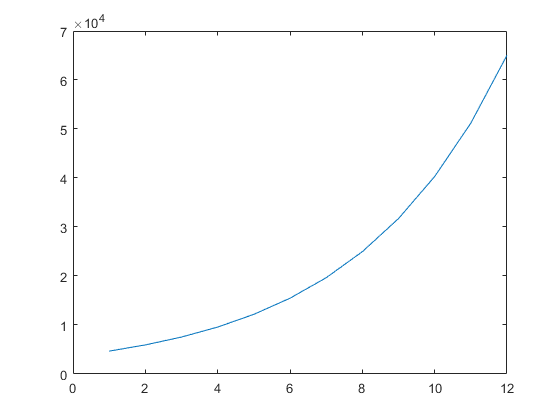

lambda=1*10^-10;

difforder=1;
MAXITR = d;


nselect = floor(logspace(log10(2*dof/N),-0.1,MAXITR)*N);
plot(nselect)


% MAXITR = d;
% nselect = ones([1,MAXITR])*N;


[TN,Vm,Vp,res1,res2] = optimTT(TN,Vm,Vp,un,zeta,MAXITR,nselect,lambda,difforder);
rez = [rez res1];

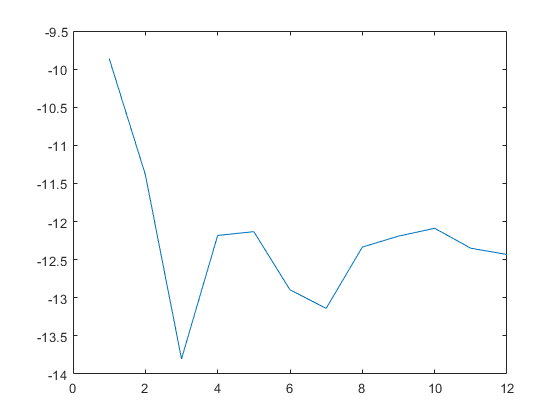


plot(log(res1))

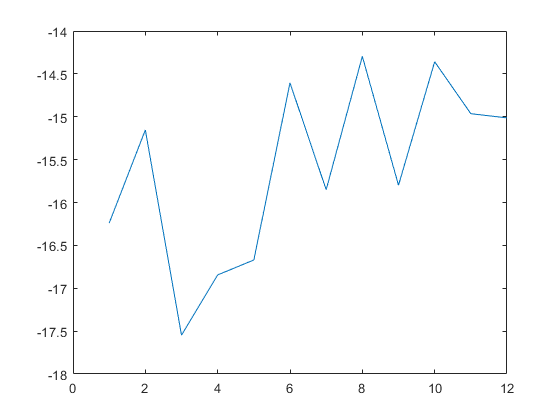

plot(log(res2))


trainerror = res1(end);

% plot(rez)

Evaluate Train data

% 
% yhattrain  = evalspline(TN,featurez,n,m);
% 
% figure;
% hold on
% plot(zeta)
% plot(yhattrain)
% hold off
% axis([0 inf -inf inf]);
% 
% erboiz = (yhattrain-zeta);
% VAF = 1-var(erboiz)/var(zeta)
% MSE = immse(yhattrain,zeta)



Evaluate Test data


yhat = evalspline(TN,tfeaturez,n,m);
erboi = (yhat-yt);
% histogram((erboi)');
VAF = 1-var(erboi)/var(yt)

VAF = 1.0000

MSE = immse(yhat,yt)

MSE = 1.6858e-07



RMSE = sqrt(immse(0.8*yhat,0.8*yt))

RMSE = 3.2847e-04

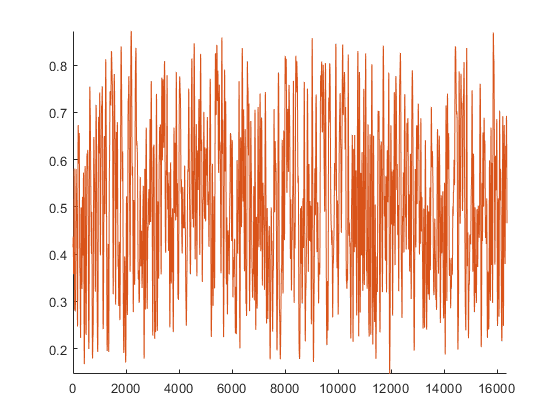


figure
hold on
plot(yt)
plot(yhat)
hold off
axis([0 inf -inf inf])

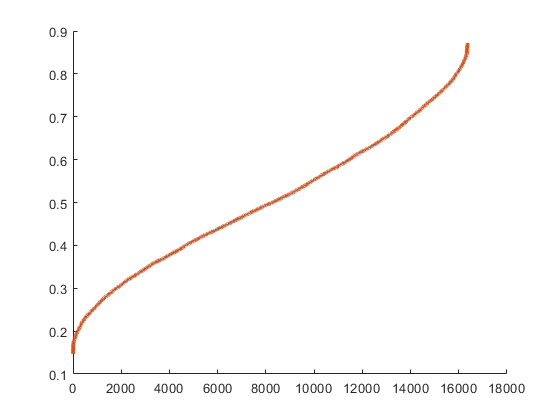


%  Visualize errors
[sortout,Iss]=sort(yhat);
figure
hold on
plot(yt(Iss))
plot(sortout,'Linewidth',3)
hold off


% FY = mag2db(abs(fft(yhat)));
% FZ = mag2db(abs(fft(yt)));
% 
% figure;
% hold on
% plot(FZ(1:floor(end/2)))
% plot(FY(1:floor(end/2)))
% hold off



% siminput = tinput;
% simoutput = toutput;
% numz = numel(outlags);
% beginz = max(outlags(end),inlags(end)) +1;
% for j = beginz+300:length(tinput)
% simfeaturez = [simoutput(j-outlags(end:-1:2))' siminput(j-inlags(1:end))'];
% simfeaturez(simfeaturez<0)=0;
% simfeaturez(simfeaturez>1)=1;
% simoutput(j) = evalspline(TN,simfeaturez,n,m);
% end

[simoutput] = simnarx(TN,tinput,toutput,inlags,outlags,n,m);
fig=figure

fig =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 4
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


hold on
plot(toutput(1:length(simoutput)),'linewidth',2)
plot(simoutput(1:length(simoutput)),'linewidth',2)
hold off
axis([0 2000 0 1])
RMSE = sqrt(immse(0.8*toutput,0.8*simoutput))

RMSE = 0.0724

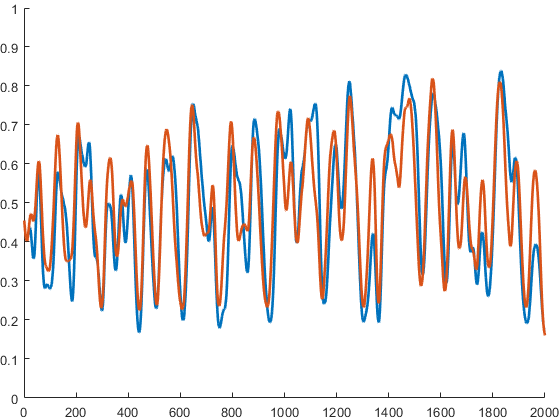


T = get(gca,'tightinset');
set(gca,'position',[T(1) T(2) 1-T(1)-T(3) 1-T(2)-T(4)]);
print(fig,'figures/wienersim','-depsc')


% simfeaturez = tfeaturez;
% simfeaturez(boolean(eye(9)))
% 
% diag(ones(1,5),-1)
% 
% ones(5,2)
toc

Elapsed time is 16.290587 seconds.
